bpath = '/Users/dh/workspace/BDL/demapper/results/cme/mappers_cmev5MH.json/';

p = [bpath, 'compute_degrees_from_TCM/avgstat_BDLMapperMH_wtd-pen_16_20_40_4.1D'];

degs = read_1d(p);



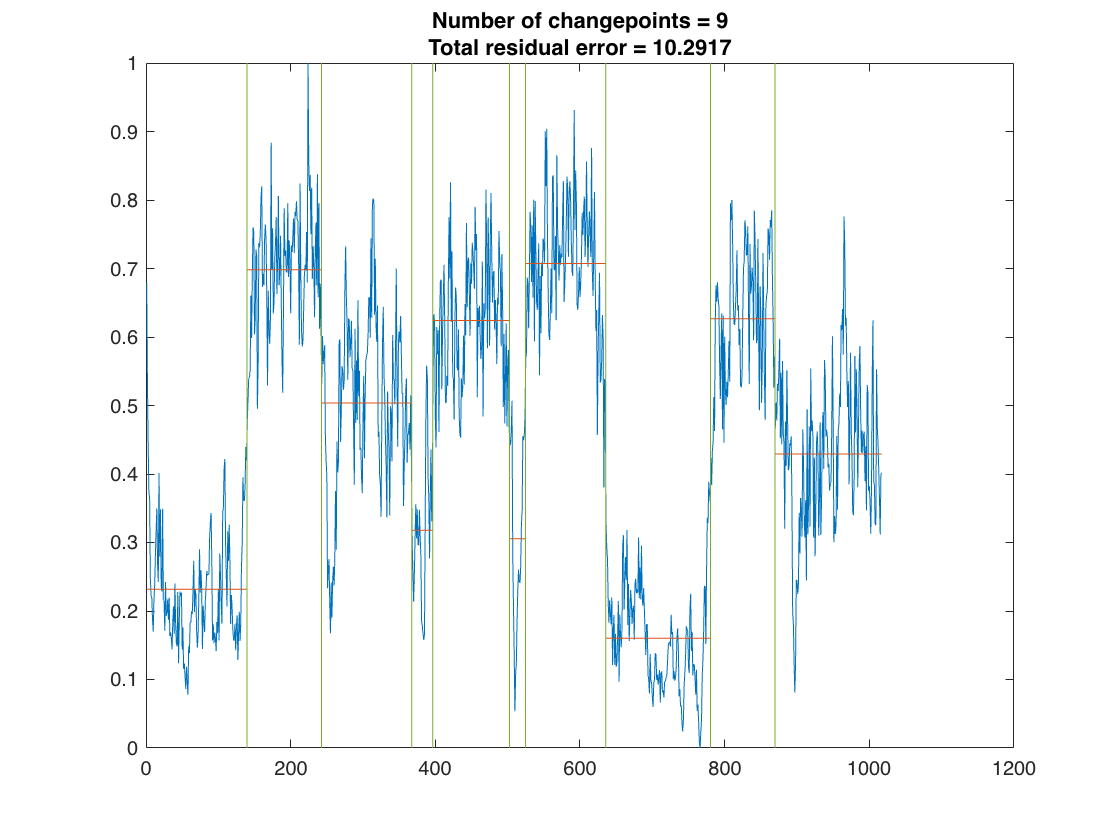

findchangepts(degs, 'MaxNumChanges', 9,'Statistic','mean', 'MinDistance', 20)

d2 = movmean(degs, 2)

d2 =     0.6788    0.6056    0.4871    0.4084    0.3690    0.3052    0.2349    0.2215    0.2044    0.1790    0.1927    0.2267    0.2597    0.2997    0.3337    0.3091    0.2555    0.3219    0.3403    0.3140    0.2927    0.2326    0.2888    0.2824    0.2152    0.1931    0.2068    0.2175    0.1952    0.2074    0.2023    0.2035    0.1915    0.1661    0.1649    0.1524    0.1639    0.1953    0.1868    0.2036    0.2099    0.1663    0.1507    0.1880    0.1757    0.1542    0.2066    0.2250    0.2243    0.1854


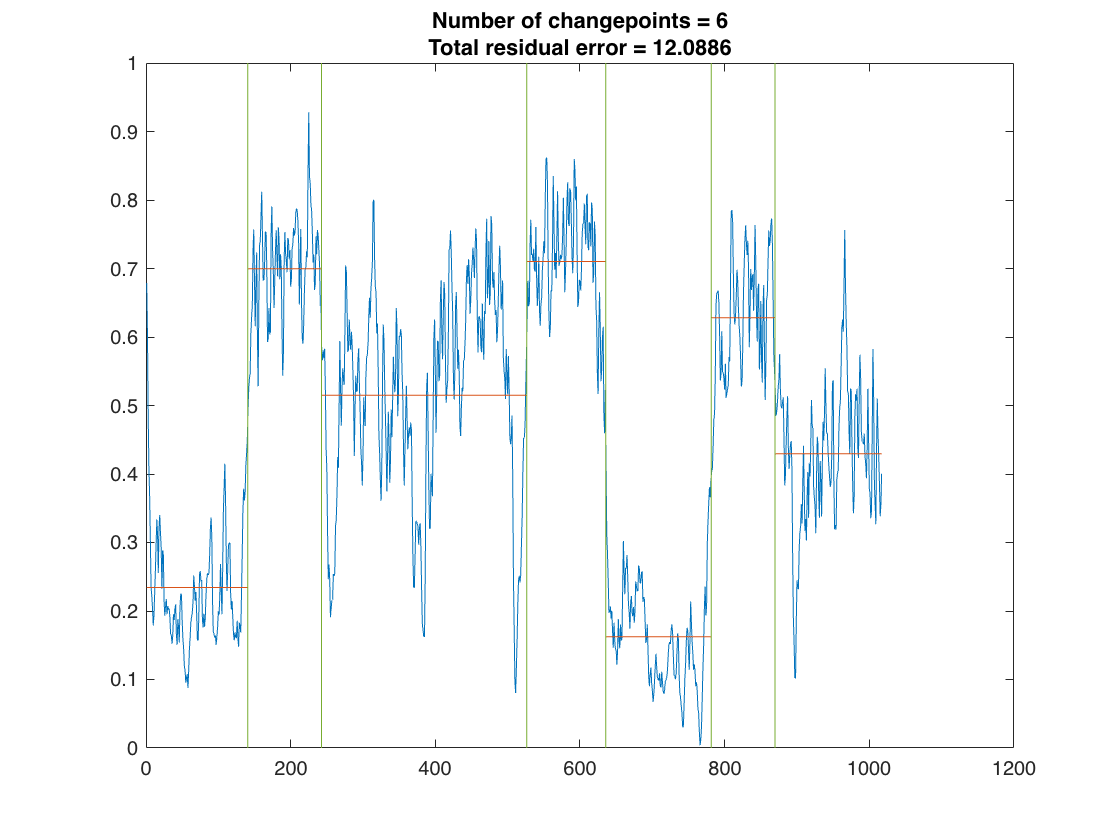

findchangepts(d2, 'MaxNumChanges', 7,'Statistic','mean')

fn_timing = '/Users/dh/workspace/BDL/neurolens/data/data-cme-shine375/timing.csv';
output_dir = bpath;


timing_table = readtable(fn_timing, 'FileType', 'text', 'Delimiter', ',');
timing_table.task_name = string(timing_table.task_name);
timing_labels = timing_table.task_name;
timing_arr = timing_table.task;
timing_changes = find([timing_arr(2:end) - timing_arr(1:end-1); 1]);
target_chgs = findchangepts(timing_arr', 'MaxNumChanges', 15);



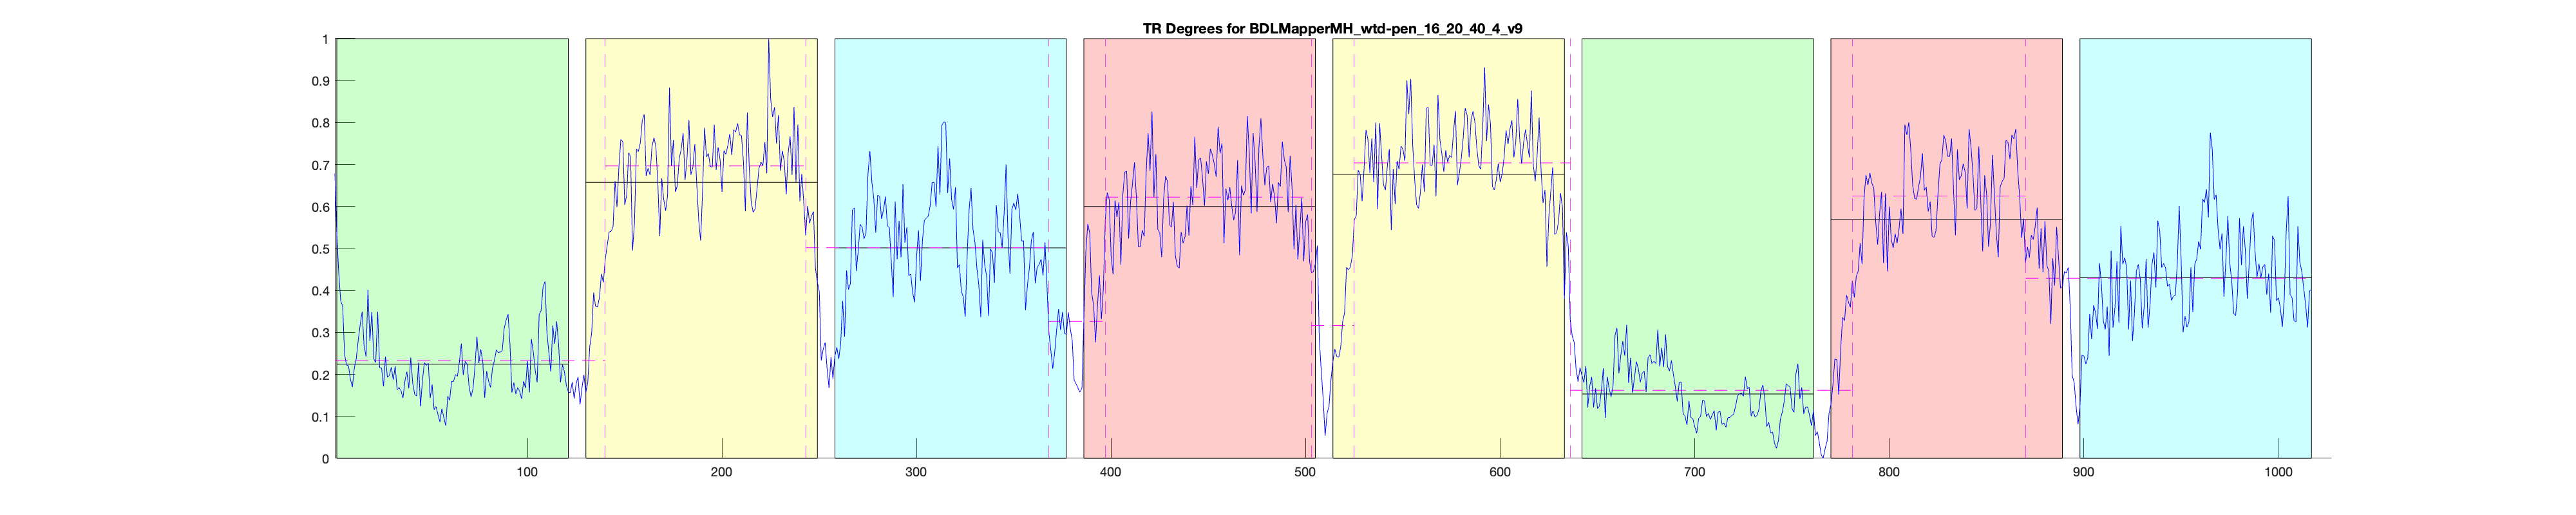


chgs = findchangepts(degs, 'MaxNumChanges',9,'Statistic','mean', 'MinDistance', 20);

mapper_name = 'BDLMapperMH_wtd-pen_16_20_40_4_v9';
output_path = fullfile(bpath, ['plottest-', mapper_name, '.png']);
plot_degs(degs, timing_labels, timing_changes, chgs, mapper_name, output_path);

function data = read_1d(data_path)
data_opts = delimitedTextImportOptions('Delimiter', ' ');
data = readmatrix(data_path, data_opts);
data = str2double(data);
end


function plot_degs(degs, timing_labels, timing_changes, chgs, mapper_name, output_path)
    f = figure;
    f.Position = [f.Position(1:2) 2000 400];
    hold on;
    
    for cid = 2:length(timing_changes)
        ch1 = timing_changes(cid-1)+1;
        ch2 = timing_changes(cid);
        assert(strcmp(timing_labels(ch1), timing_labels(ch2)))
        label = timing_labels(ch1);
    
        col = '';
        switch label 
            case 'instruction'
                continue
            case 'rest'
                col = 'g';
            case 'math'
                col = 'red';
            case 'memory'
                col = 'yellow';
            case 'video'
                col = 'cyan';
        end
    
        patch([ch1 ch2 ch2 ch1], [0 0, 1, 1], col, 'FaceAlpha', .2)
    
        avg_deg = mean(degs(1, ch1:ch2));
        plot(ch1:ch2, repmat(avg_deg, ch2-ch1+1, 1), 'black');
    end

    for ch=chgs
        xline(ch, '--m')
    end
    for i=0:length(chgs)
        x1 = 1;
        x2 = length(degs);
        if i > 0
            x1 = chgs(i);
        end
        if i < length(chgs)
            x2 = chgs(i+1);
        end

        vs = mean(degs(x1:x2));
        plot([x1,x2], [vs, vs], '--m')
    end
    
    plot(1:length(degs), degs, 'blue')
    xlim([1,length(degs) * 1.01])
    title(['TR Degrees for ', mapper_name], 'Interpreter', 'none')

    saveas(f, output_path);
    close(f);
end